clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, %title, %%legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultlegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('point.mat')
point

point = struct with fields:
       Mach: [5×12×7 double]
    Spacing: [5×12×7 double]
    Stagger: [5×12×7 double]
      Angle: [5×12×7 double]
     output: [1×1 struct]
    output0: [1×1 struct]



%[Machs,Spacings,Stagger] = meshgrid([Machs,Spacings,Stagger]);

Machs = [1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
Spacings = [0.25,0.375,0.5,0.625,0.75];
Staggers = [-0.5,-0.25,-0.1,0,0.1,0.25,0.5];
% In Gmsh this was defined as: 
    % stag = -0.1*c;
    % Point(n) = {(point-stag, H/2, 0, meshouteruf};
    % Thus a negative stagger makes a positive change i.e. -x=aft, +x=fore
    % Ideally we want i.e. +x=aft, -x=fore, we will convert later
    
% LOAD IN VALUES (CONVERT MOMENT DIRECTION)
cm = -point.output0.cm;         % Minus sign for right-to-left hand
cd = point.output0.cd;
cl = point.output0.cl;
cmMa2 = -point.output0.moment;  % Minus sign for right-to-left hand
cdMa2 = point.output0.dragm;
clMa2 = point.output0.lift;

% Corrections
% point at (0.75H,1.8Ma,0.1x)
cdMa2(5,5,5) = 0.05

cdMa2 = cdMa2(:,:,1) =

    0.0505    0.0557    0.0643    0.0642    0.0529    0.0400    0.0500    0.0630    0.0784    0.0960    0.1153    0.1356
    0.0584    0.0529    0.0505    0.0682    0.0957    0.1267    0.1544    0.1696    0.1722    0.1716    0.1701    0.1679
    0.0586    0.0717    0.0916    0.1341    0.1492    0.1431    0.1354    0.1268    0.1182    0.1102    0.1024    0.0948
    0.0811    0.1029    0.1295    0.1304    0.1151    0.1001    0.0875    0.0765    0.0663    0.0585    0.0633    0.0700
    0.1019    0.1178    0.1240    0.0990    0.0774    0.0621    0.0525    0.0589    0.0670    0.0763    0.0865    0.0973


cdMa2(:,:,2) =

    0.1735    0.1921    0.2088    0.2205    0.2320    0.2430    0.2551    0.2687    0.2820    0.2963    0.3086    0.3185
    0.1542    0.1692    0.1798    0.1849    0.1883    0.1910    0.1869   -0.0151    0.0813    0.0864    0.0846    0.0829
    0.1515    0.1652    0.1709    0.1690    0.1529    0.0703    0.0658    0.0620    0.0552    0.0586    0.0642 

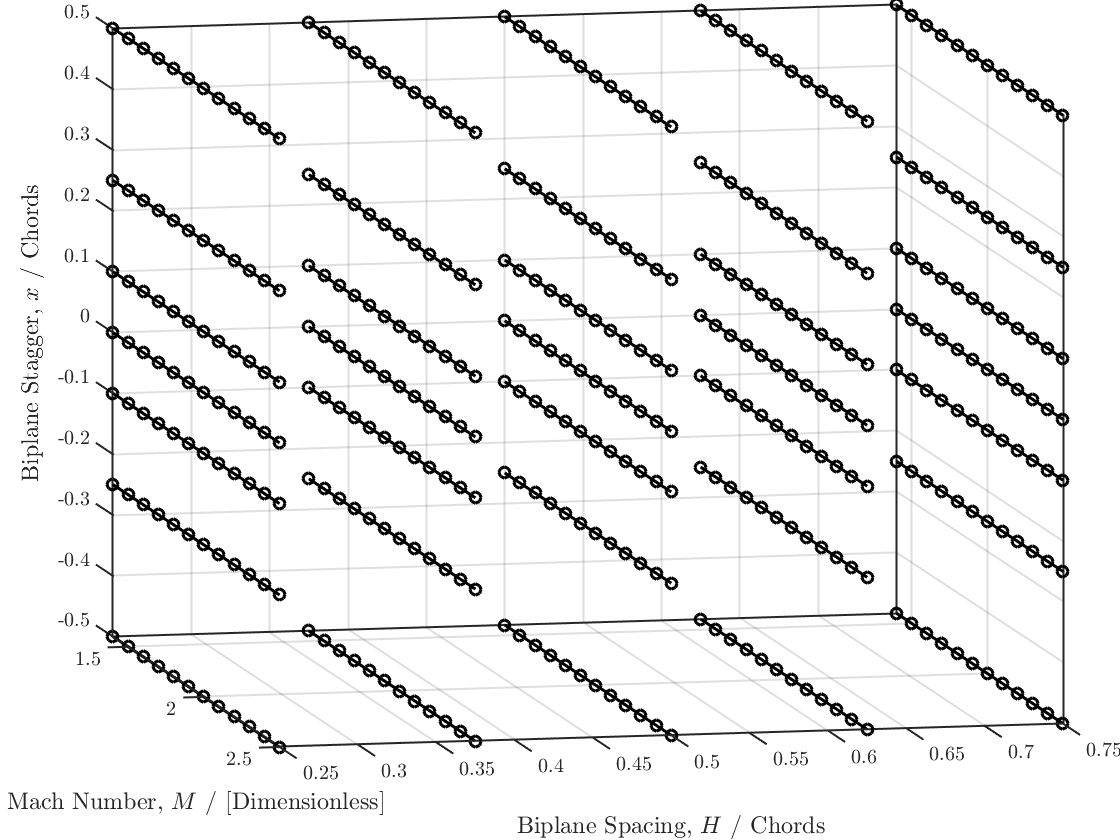

cd(5,5,5) = cdMa2(5,5,5)./(1.8^2);
% point at (0.75H,1.8Ma,-0.1x)
cdMa2(5,5,3) = 0.13;
cd(5,5,3) = cdMa2(5,5,3)./(1.8^2);
% point at (0.375H,2.1Ma,0.25x)
cdMa2(2,8,6) = 0.14;
cd(2,8,6) = cdMa2(2,8,6)./(2.1^2);
% point at (0.375H,2.1Ma,-0.25x)
cdMa2(2,8,2) = 0.10;
cd(2,8,2) = cdMa2(2,8,2)./(2.1^2);

LoverD = cl./cd;

[cds,cdc,started_locations,choked_locations] = cd_isstarted(cd,0.060);
[cms,cmc]=splitmatrix(cm,started_locations,choked_locations);
[cls,clc]=splitmatrix(cl,started_locations,choked_locations);
[cmMa2s,cmMa2c]=splitmatrix(cmMa2,started_locations,choked_locations);
[cdMa2s,cdMa2c]=splitmatrix(cdMa2,started_locations,choked_locations);
[clMa2s,clMa2c]=splitmatrix(clMa2,started_locations,choked_locations);
[LoverDs,LoverDc]=splitmatrix(LoverD,started_locations,choked_locations);

X=point.Mach;
Y=point.Spacing;
Z=-(point.Stagger);                           % Minus sign for conventional direction
Staggers = -[-0.5,-0.25,-0.1,0,0.1,0.25,0.5]; % Minus sign for conventional direction
viewangle=[79.693 10.462];

for i =1:length(Spacings)
    for j =1:length(Staggers)
plot3(X(i,:,j),Y(i,:,j),Z(i,:,j),'-','LineWidth',width,'MarkerSize',msize,'Color',black)    % draw the scatter plot
hold on
plot3(X(i,:,j),Y(i,:,j),Z(i,:,j),'o','LineWidth',width,'MarkerSize',0.7*msize,'Color',black)
hold on
    end
end

grid on; box on; hold on
%%title("\textbf{Sampling Grid for proscribed angle of attack}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
H=gca; H.LineWidth=1;
%ylim([0.2 0.9])
%zlim([0 8000])
%xlim([1.4 2.2])
view([78 10.5])
%%legend('OpenFOAM run', 'Sample Points','Location',"best")
hold off
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);

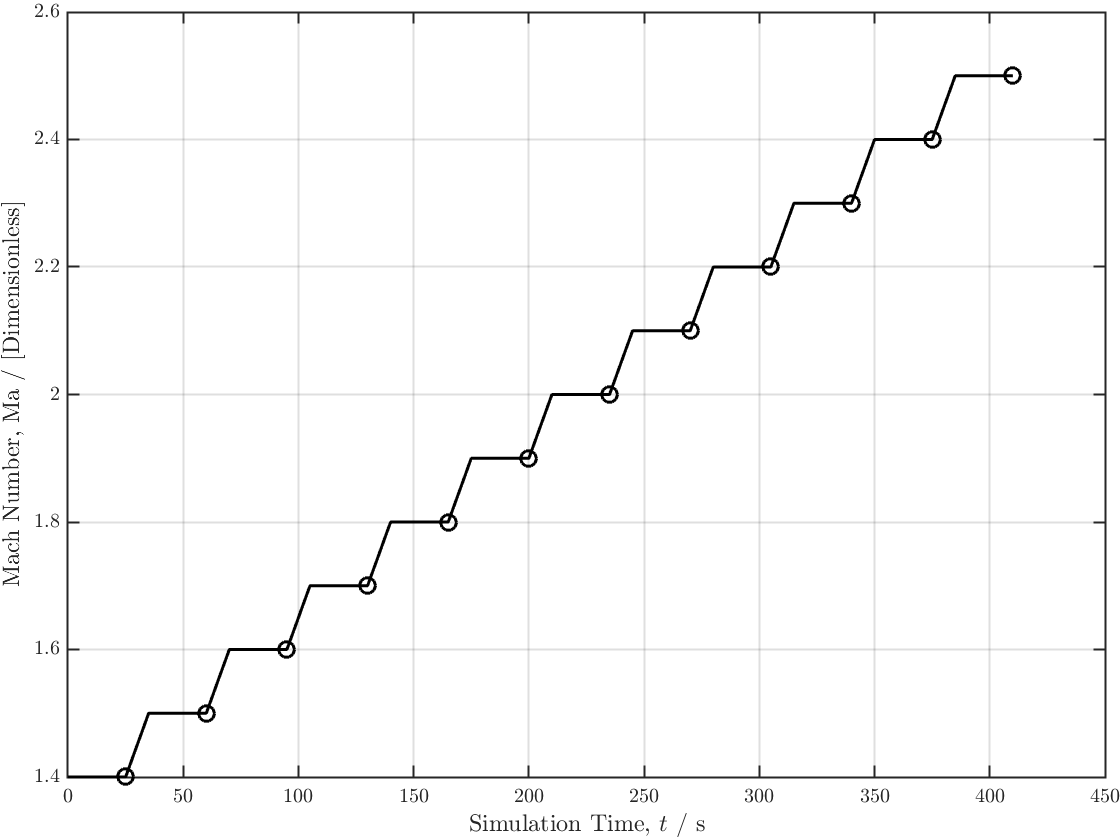

H=gca; H.LineWidth=1;

t_hold =25; t_ramp =10;
Machs_all = reshape( cat( 1, [Machs], [Machs] ), 1, [] );
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end

t_sampling=t_all(2:2:end);         

figure
plot(t_all,Machs_all,'k-','LineWidth',width,'MarkerSize',msize)
hold on
plot(t_sampling,Machs,'ko','LineWidth',width,'MarkerSize',msize)
grid on; box on; hold on
%%title("\textbf{Sampling Run axross a range of Mach Number for one Geometry}",'FontSize',tsize)
ylabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
xlabel("Simulation Time, $t$ / s",'FontSize',lsize)
%%legend('Inflow Velocity', 'Sample Points','Location',"southeast")
hold off
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

cmap = parula;

figure
FancyScatter3s(cmMa2s,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cmMa2c,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'$C_{m}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.3905    0.4117


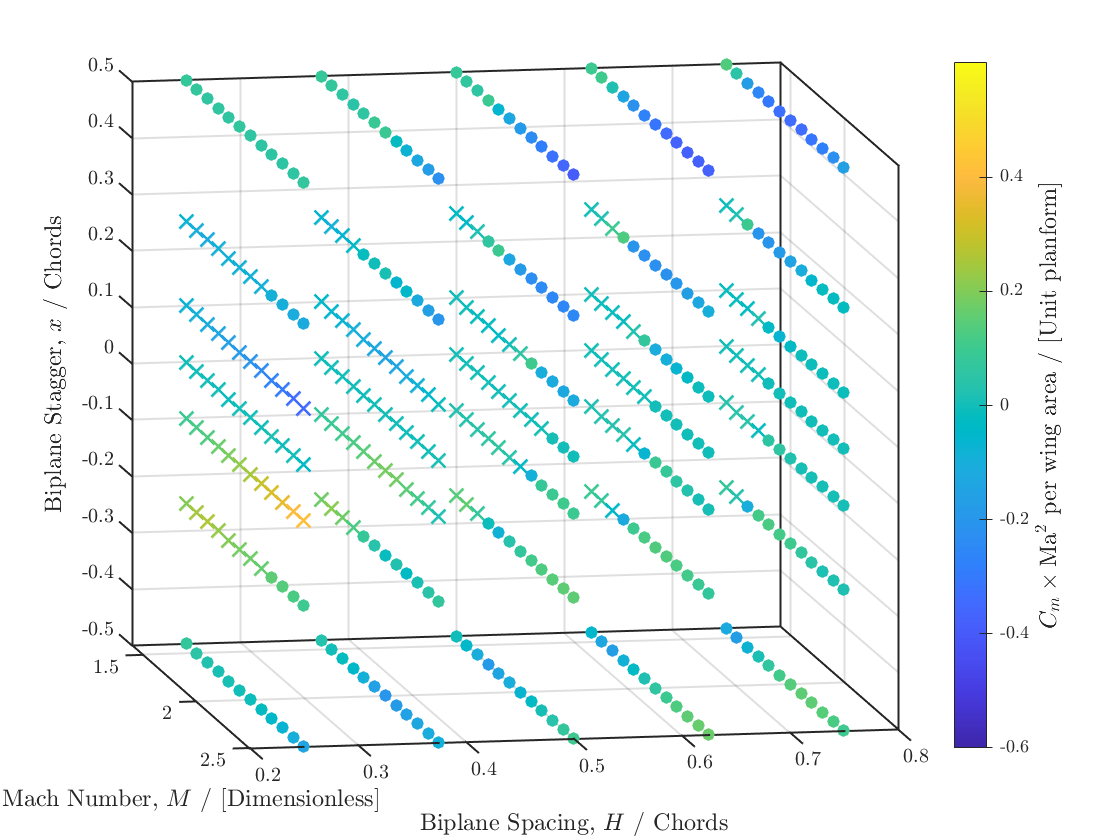

caxis([-0.6 0.6])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.6 0.6]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{m}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_cmMa2_scatter.png')


figure
FancyScatter3s(cmMa2s,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cmMa2c,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.3905    0.4117


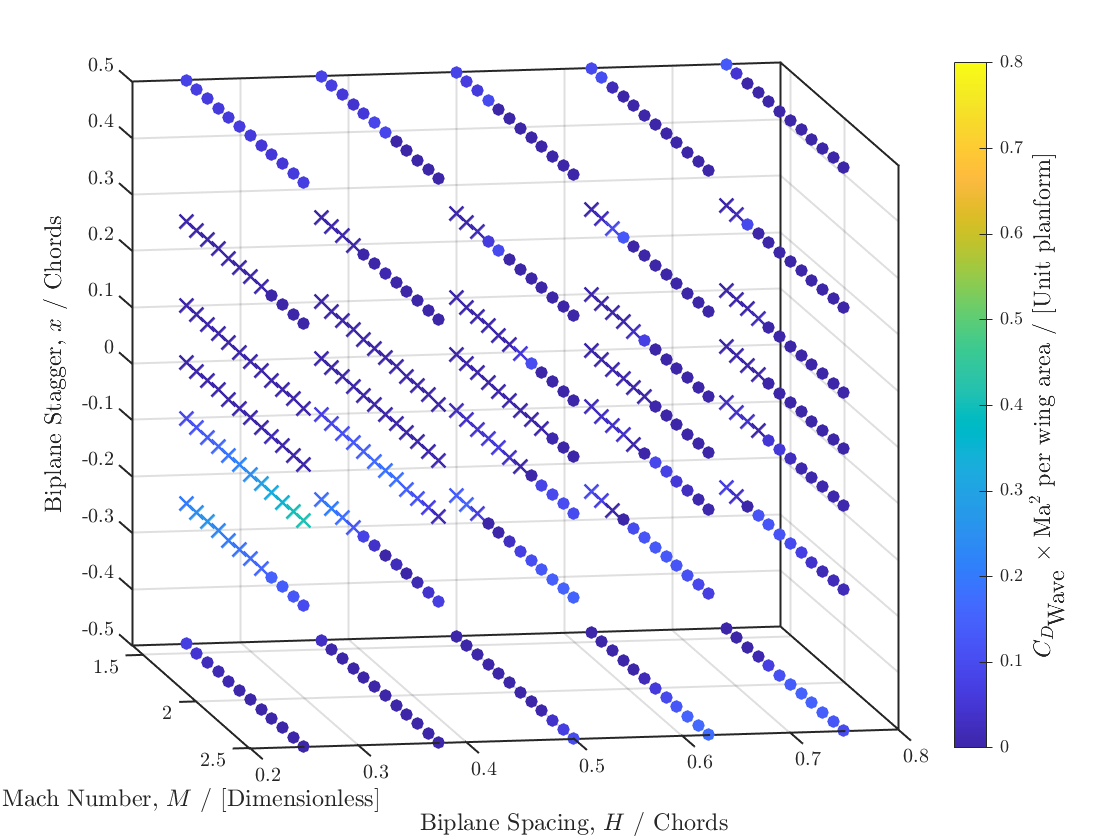

caxis([0 0.8])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [0 0.8]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{D_{\textrm{Wave}}}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_cdMa2_scatter.png')


figure
FancyScatter3s(clMa2s,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(clMa2c,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'$C_{L}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.6484    0.6525


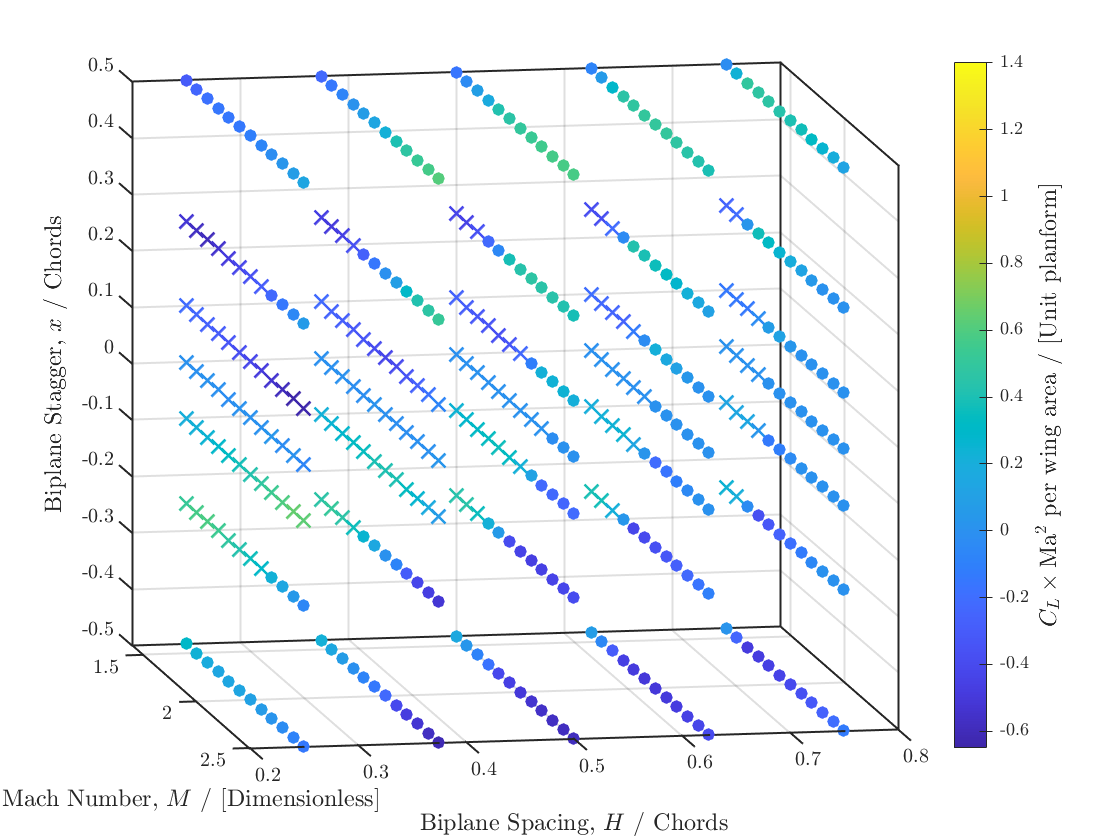

caxis([-0.65 1.4])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.65 1.4]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{L}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_clMa2_scatter.png')


figure
FancyScatter3s(cms,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cmc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

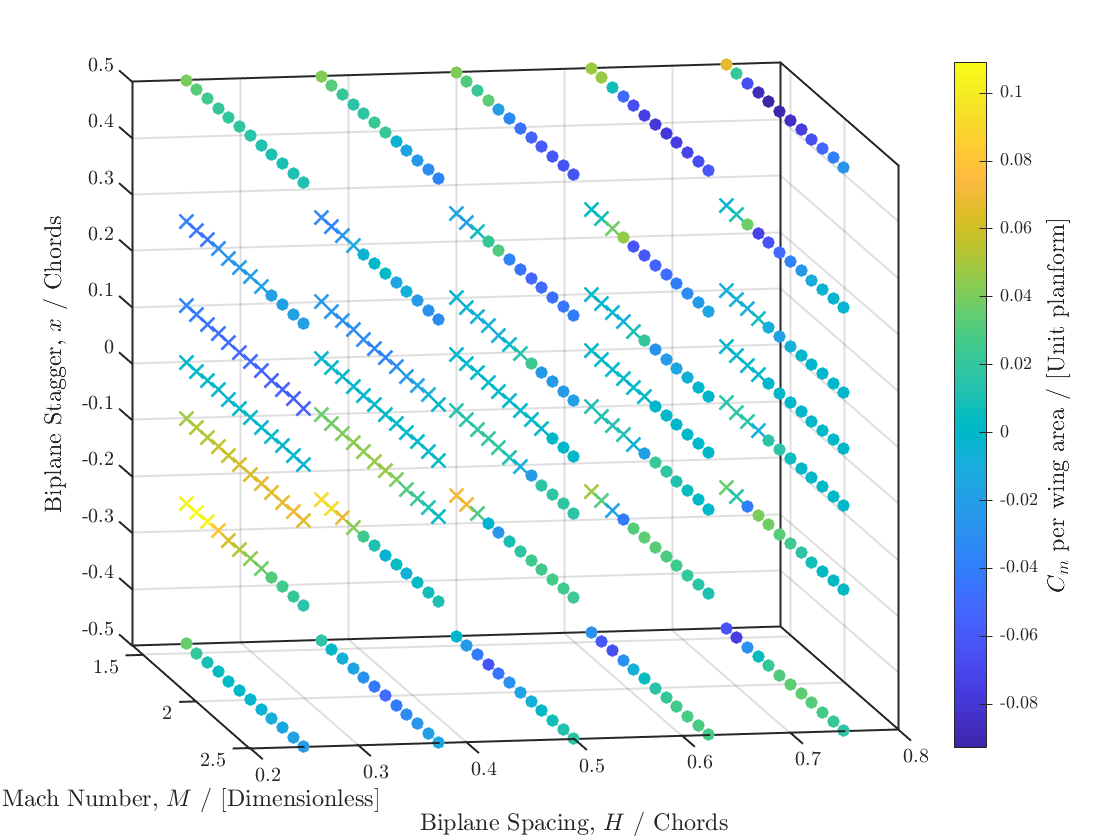

grid on; box on; hold on
%title({'\textbf{Moment Coefficient} $C_{m}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
%caxis
%caxis([-0.15 0.15005])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
%set(c, 'ylim', [-0.15 0.15005]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{m}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_cm_scatter.png')


figure
FancyScatter3s(cds,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(cdc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Wave Drag Coefficient} $C_{D_\textrm{Wave}}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =     0.0022    0.1336


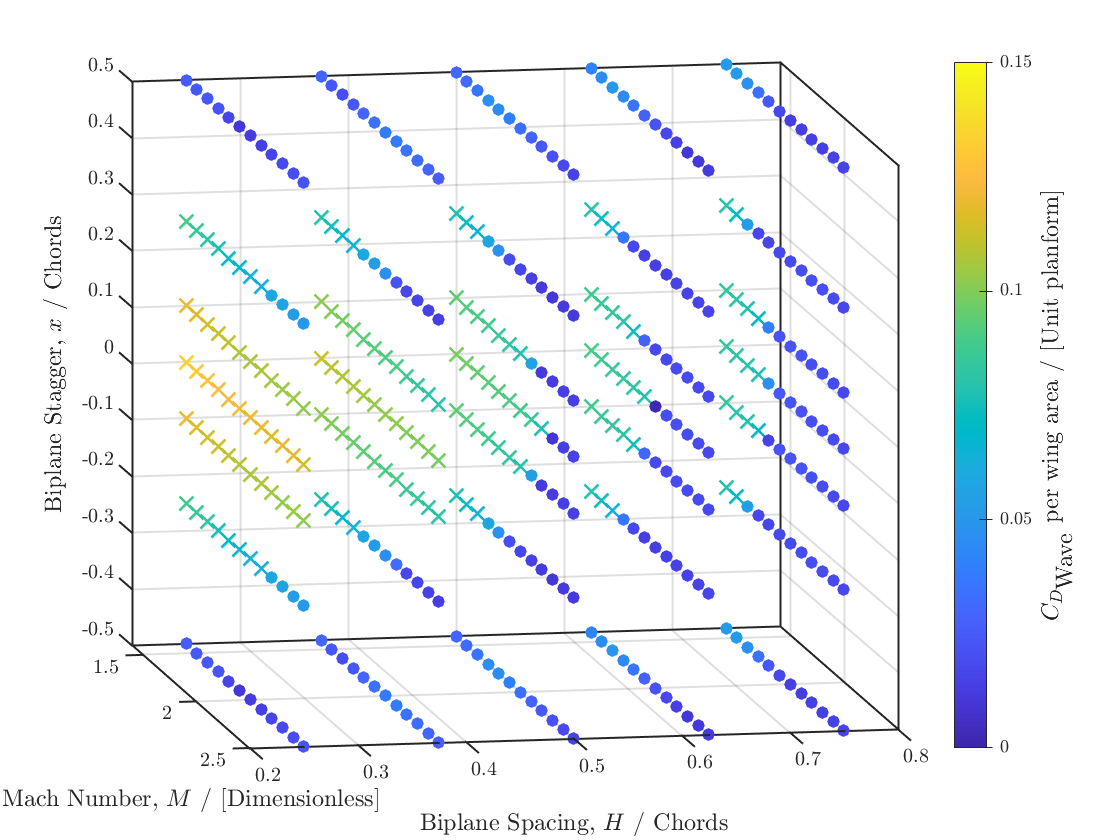

caxis([0 0.15])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [0 0.15]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{D_{\textrm{Wave}}}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_cd_scatter.png')

% 
% Ma_fig_23a_machs = [0.3:0.1:2.5];
% Ma_fig_23a_stags = [0,0.1,0.3,0.4,0.5,0.6,0.8,0.85,0.85,0.90,1.00,0.45,0.40,0.10,0,0,0,0,0,0,0,0,0];
% % machs and drags:  diamond, buse accel, buse decell, continuous
% Ma_fig_23b_drag_continuous = [0.004481132075471710,0.002358490566037760,0.0014150943396226400,0.0028301886792452800,0.006839622641509450,0.017216981132075500,0.03797169811320760,0.039150943396226400,0.03702830188679250,0.033962264150943400,0.022877358490566000,0.02051886792452830,0.01627358490566040,0.0037735849056603800,0.0028301886792452800,0.003537735849056620,0.006132075471698110,0.008254716981132090,0.009669811320754730,0.01108490566037740,0.012264150943396200,0.013443396226415100,0.014858490566037700];
% 
% xx=Ma_fig_23a_machs
% zz=Ma_fig_23a_stags
% dd=Ma_fig_23b_drag_continuous
% yy = 0.5*(ones(1,length(Ma_fig_23a_machs)))
% 
% figure
% for j =1:length(Spacings)
% for i =1:length(Staggers)
% scatter3(X(j,:,i),Y(j,:,i),Z(j,:,i),40,cd(j,:,i),'filled')    % draw the scatter plot
% hold on
% end
% end
% grid on; box on; hold on
% %title({'\textbf{Wave Drag Coefficient} $C_{D_\textrm{Wave}}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
% xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
% ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
% zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
% h=color_line3(xx,yy,zz,dd,'LineStyle','-','Marker','x',"LineWidth",width,'markerSize',msize) %// color binded to "y" values
% view(viewangle)
% caxis
% caxis([0 0.15])
% c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
% set(c, 'ylim', [0 0.15]); % set your range here
% xlim([1.4 2.5])
% ylim([0.2 0.8])
% zlim([-0.5 0.5])
% colormap(cmap); % apply new colormap
% ylabel(c,'$C_{D_{\textrm{Wave}}}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
% H=gca; H.LineWidth=1; hold off
% %saveas(gcf,'alfa0_cd_scatter.png')


figure
FancyScatter3s(cls,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(clc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Lift Coefficient} $C_{L}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -0.2634    0.2614


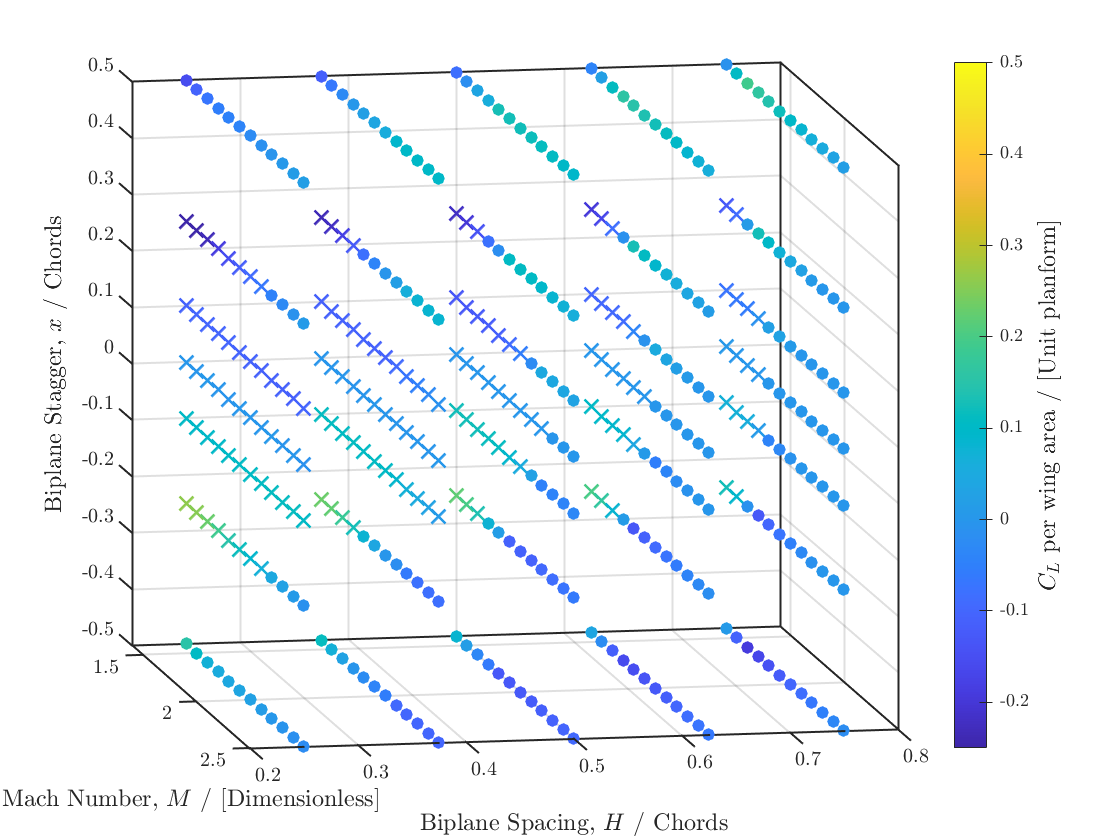

caxis([-0.25 0.5])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-0.25 0.5]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'$C_{L}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_cl_scatter.png')


figure
FancyScatter3s(LoverDs,X,Y,Z,Spacings,Staggers,viewangle)

ans = 1

hold on
FancyScatter3c(LoverDc,X,Y,Z,Spacings,Staggers,viewangle,width)

ans = 1

grid on; box on; hold on
%title({'\textbf{Lift-to-Drag Ratio} $\frac{L}{D}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle)
caxis

ans =    -8.2355    8.2286


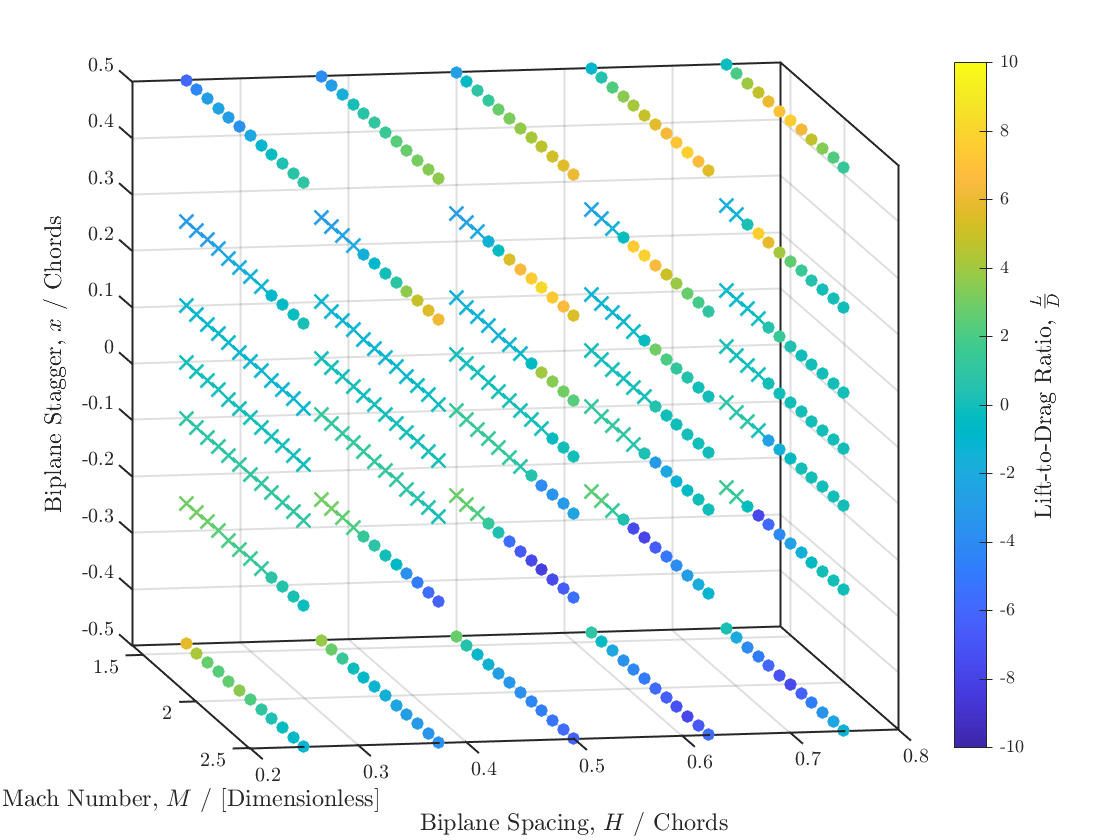

caxis([-10 10])
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both')
set(c, 'ylim', [-10 10]); % set your range here
colormap(cmap); % apply new colormap
ylabel(c,'Lift-to-Drag Ratio, $\frac{L}{D}$','Interpreter','latex','FontSize',lsize)
H=gca; H.LineWidth=1; hold off
hold off
saveas(gcf,'alfa0_loverd_scatter.png')

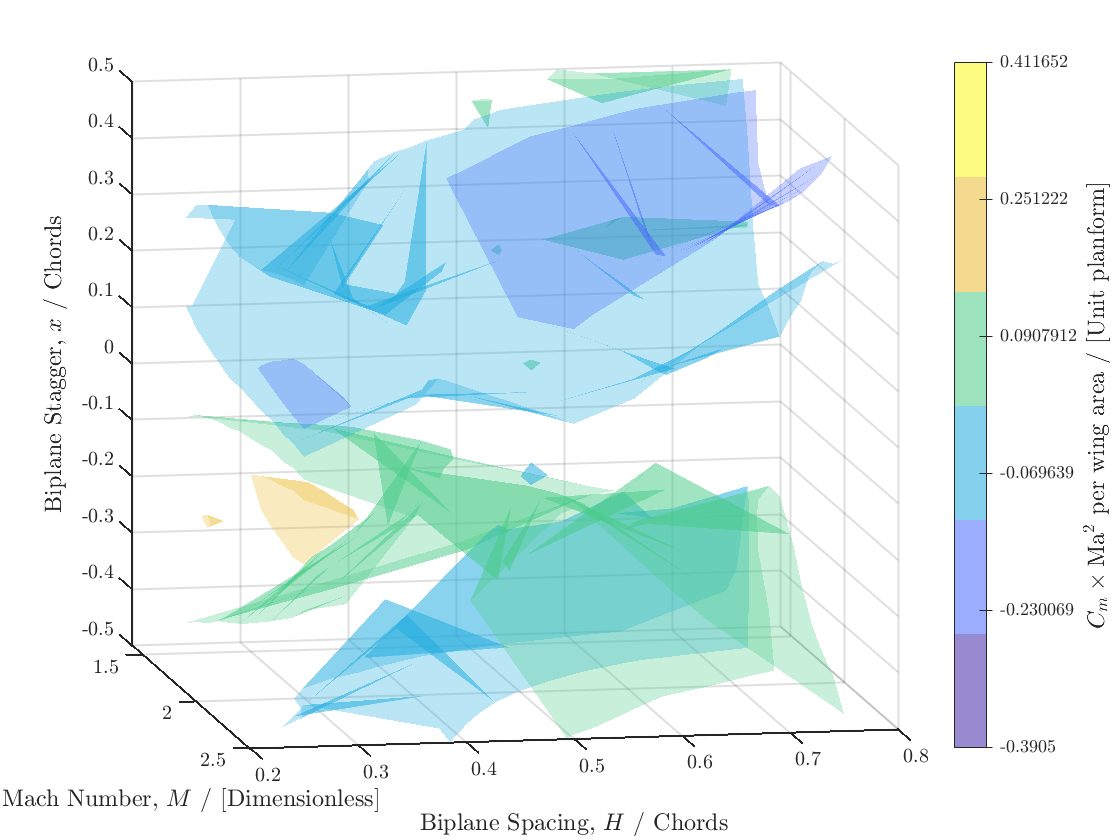

% Visualize the result

number_colors=6;

figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cmMa2,[],'all'); upper_index=max(cmMa2,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cmMa2,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cmMa2,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{m}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x$','\textbf{For constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%title({'$C_{m}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$C_{m}\times\textrm{Ma}^2, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_cmMa2_surf.png')

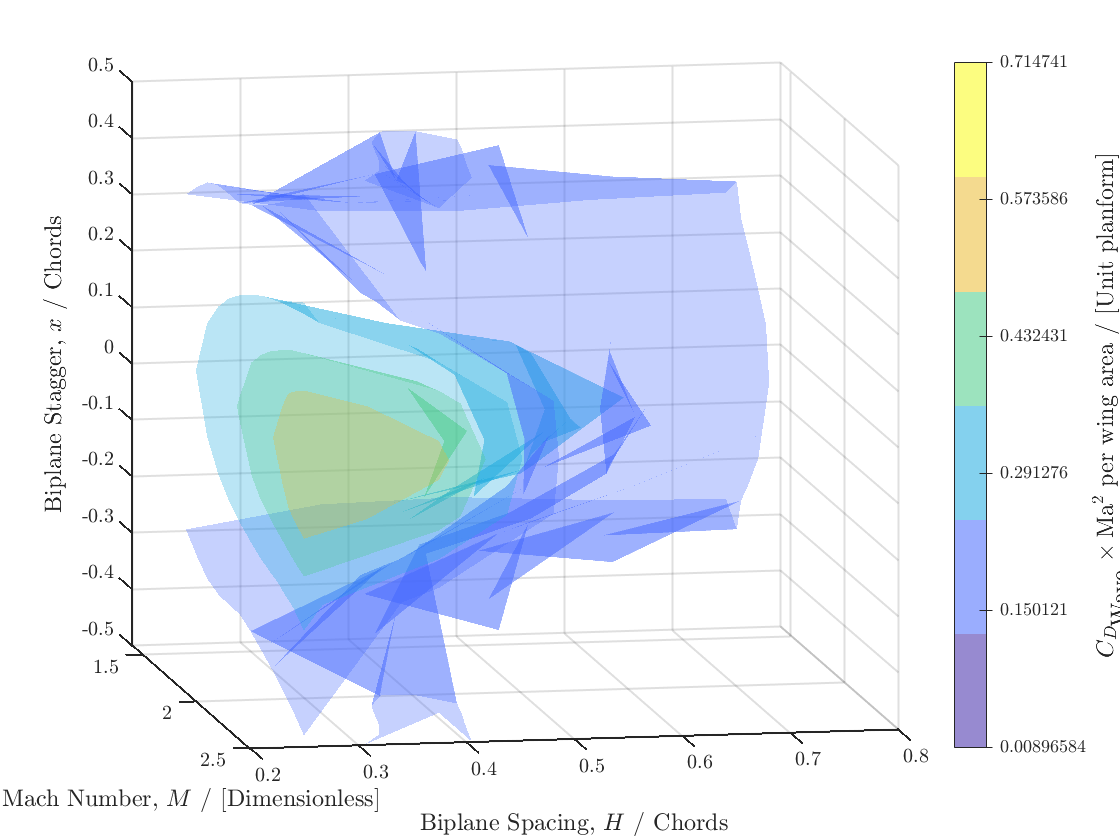


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cdMa2,[],'all'); upper_index=max(cdMa2,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cdMa2,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cdMa2,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x$','\textbf{For constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%title({'$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$C_{D_\textrm{Wave}}\times\textrm{Ma}^2, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_cdMa2_surf.png')

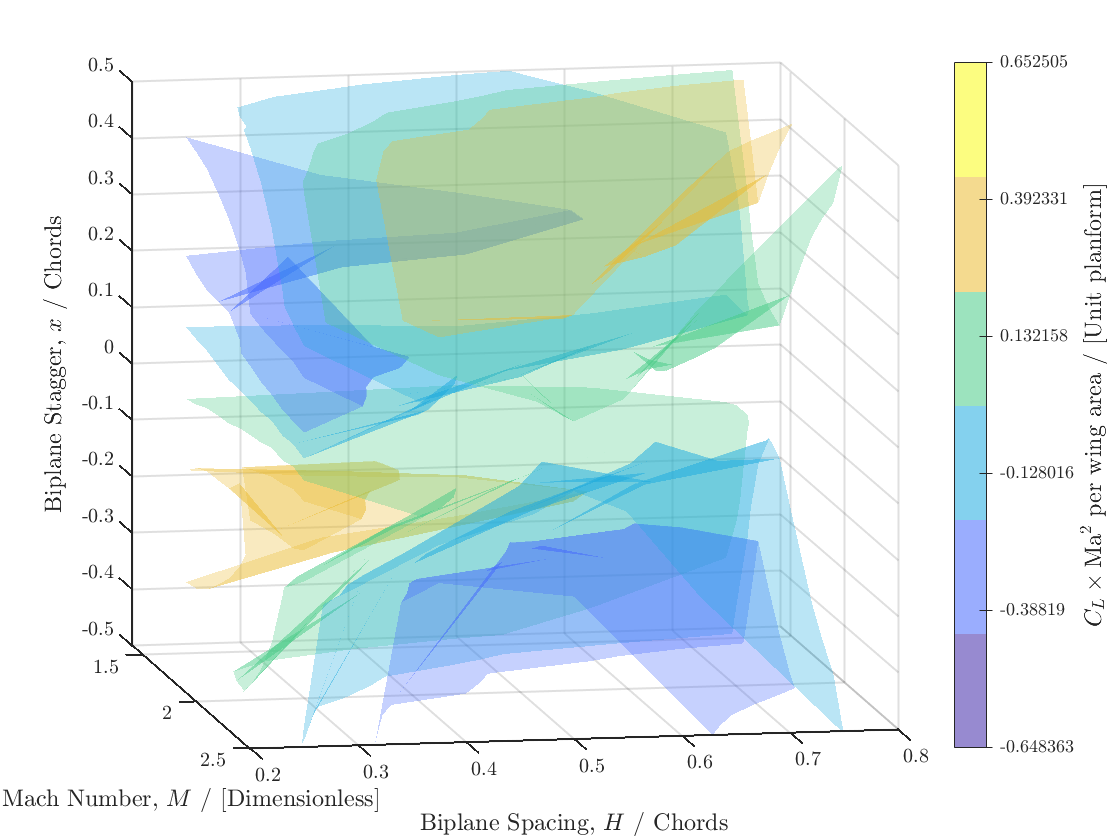


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(clMa2,[],'all'); upper_index=max(clMa2,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,clMa2,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,clMa2,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{L}\times\textrm{Ma}^2$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'$C_{L}\times\textrm{Ma}^2$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$C_{L_\textrm{Wave}}\times\textrm{Ma}^2, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_clMa2_surf.png')

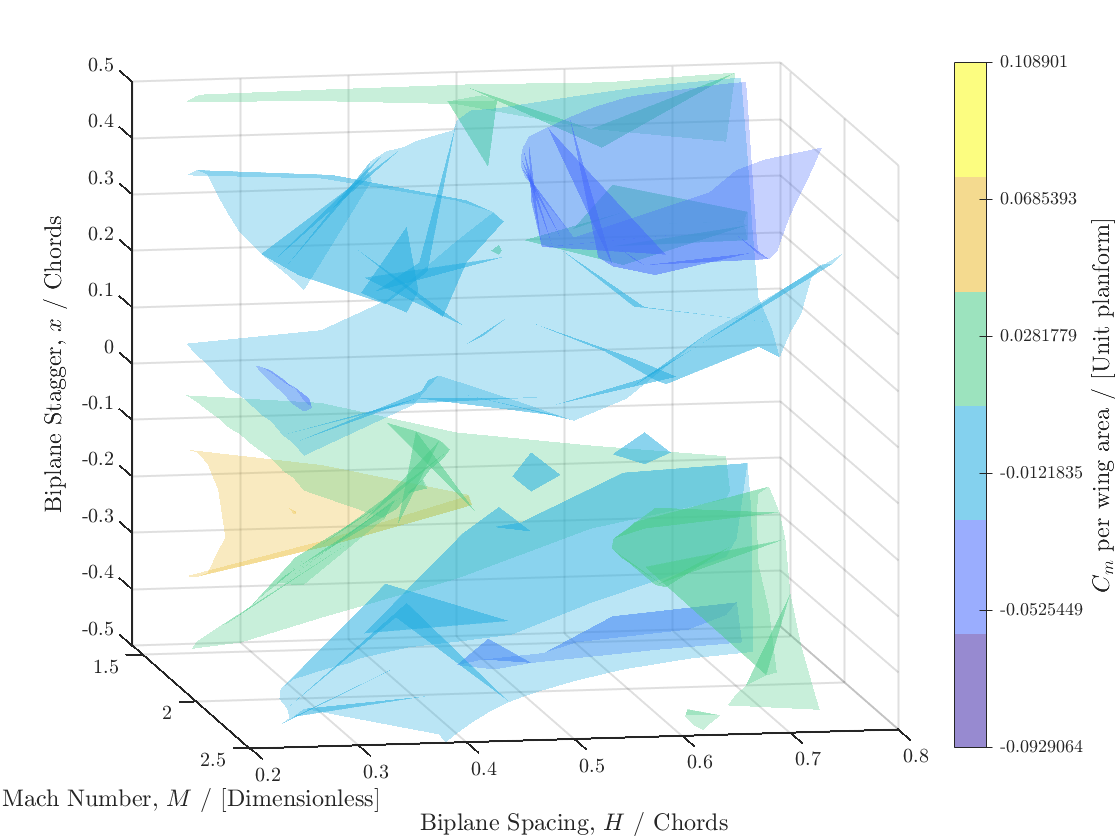


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cm,[],'all'); upper_index=max(cm,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cm,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cm,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{m}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Moment Coefficient} $C_{m}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$C_{m}, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_cm_surf.png')

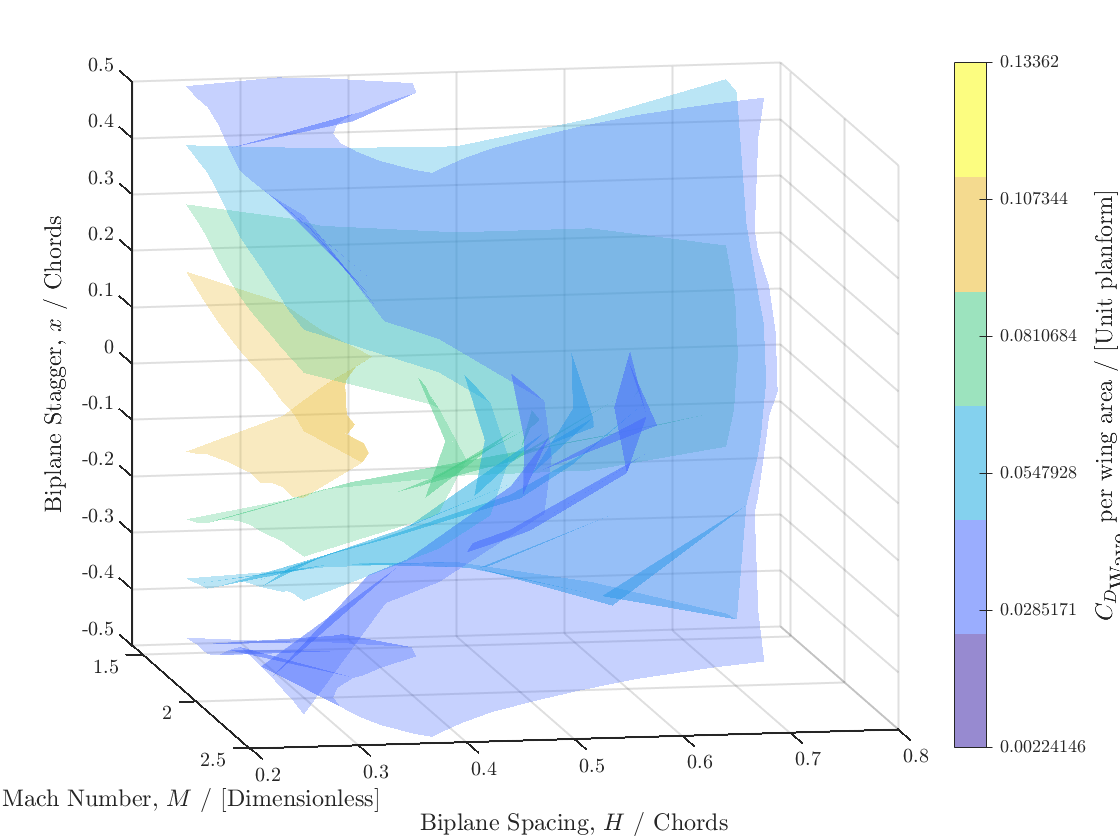


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cd,[],'all'); upper_index=max(cd,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cd,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cd,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{D_\textrm{Wave}}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Wave Drag Coefficient} $C_{D_\textrm{Wave}}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$C_{D_\textrm{Wave}}, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_cd_surf.png')

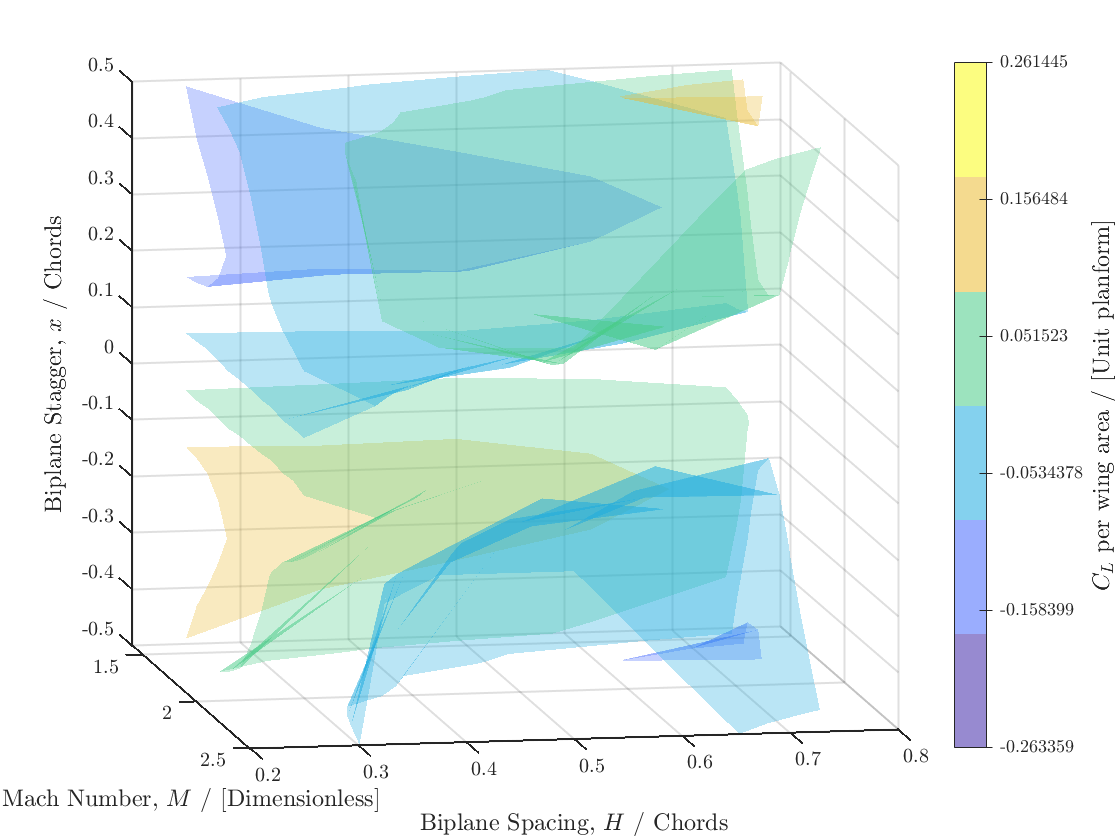


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(cl,[],'all'); upper_index=max(cl,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,cl,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,cl,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'$C_{L}$ per wing area / [Unit planform]','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Lift Coefficient} $C_{L}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$C_{L}, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_cl_surf.png')

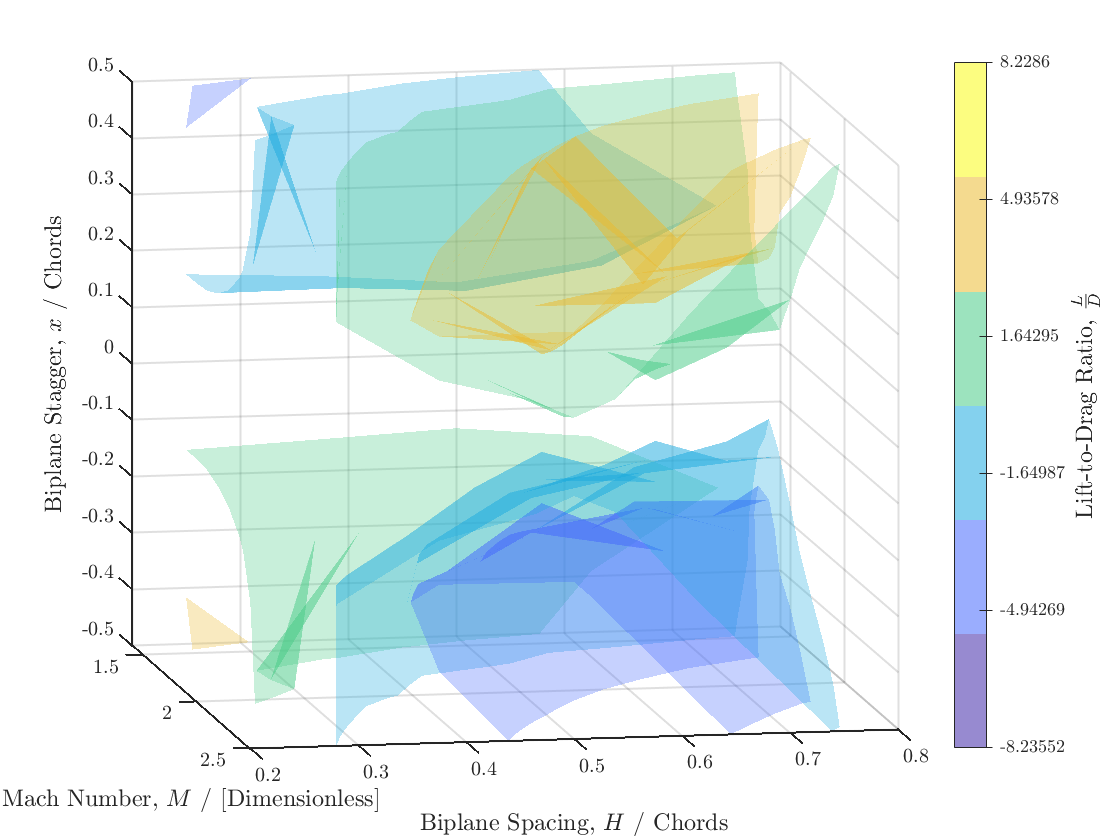


figure;%clf;
numcolours = number_colors; color = parula(numcolours); %color = jet(N);
lower_index=min(LoverD,[],'all'); upper_index=max(LoverD,[],'all');
%levels = logspace(log10(lower_index),log10(upper_index),numcolours);
levels = linspace(lower_index,upper_index,numcolours);
% set(gcf,'Visible','on')
hold on; alfa=0.3;
for i = 1:numcolours
    p = patch(isosurface(X,Y,Z,LoverD,levels(i)),...
        'FaceColor',    color(i,:),    'EdgeColor',    'none',...
        'FaceAlpha',    alfa);
    isonormals(X,Y,Z,LoverD,p)
end
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view(viewangle); grid on
%camlight('top')%headlight
lighting gouraud
%colormap(parula(numcolours));
%set(gca,'ColorScale','log')
c = colorbar; set(c,'TickLabelInterpreter','latex','TickDirection','both','Ticks',linspace(0,1,numcolours),'TickLabels',levels)%,'Limits'),[lower_index,upper_index])
%c.Ruler.Scale='log'
fudge = 1.8; alfa =fudge*alfa; %make it a bit darker for visuals
c.Colormap=((alfa*color)+((1-alfa)*[1,1,1]));
ylabel(c,'Lift-to-Drag Ratio, $\frac{L}{D}$','Interpreter','latex','FontSize',lsize)
%title({'\textbf{Lift-to-Drag Ratio} $\frac{L}{D}$ \textbf{across} $H,\textrm{Ma},x,$\textbf{ for constant} $\alpha=0^{\circ}$'},'FontSize',tsize)
%%legend('$\frac{L}{D}, \alpha=0^{\circ}$','Location','best')
H=gca; H.LineWidth=1; hold off
saveas(gcf,'alfa0_loverd_surf.png')

function h = color_line3(x, y, z, c, varargin)
% color_line3 plots a 3-D "line" with c-data as color
%
%       h = color_line(x, y, z, c)
%       by default: 'LineStyle','-' and 'Marker','none'
%
%          or
%       h = color_line(x, y, z, c, mark) 
%          or
%       h = color_line(x, y, z, c, 'Property','value'...) 
%             with valid 'Property','value' pairs for a surface object
%
%  in:  x      x-data
%       y      y-data
%       z      z-data
%       c      4th dimension for colouring
%       mark   for scatter plots with no connecting line
%
% out:  h   handle of the surface object
h = surface(...
  'XData',[x(:) x(:)],...
  'YData',[y(:) y(:)],...
  'ZData',[z(:) z(:)],...
  'CData',[c(:) c(:)],...
  'FaceColor','none',...
  'EdgeColor','interp',...
  'Marker','none');
  
if nargin ==5
    switch varargin{1}
        case {'+' 'o' '*' '.' 'x' 'square' 'diamond' 'v' '^' '>' '<' 'pentagram' 'p' 'hexagram' 'h'}
            set(h,'LineStyle','none','Marker',varargin{1})
        otherwise
            error(['Invalid marker: ' varargin{1}])
    end
elseif nargin > 5
    set(h,varargin{:})
end
end

function done = FancyScatter3(RequiredAoA,X,Y,Z,Spacings,Staggers,viewangle)
for a =1:length(Spacings)
for b =1:length(Staggers)
scatter3(X(a,:,b),Y(a,:,b),Z(a,:,b),40,RequiredAoA(a,:,b),'filled')    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
view(viewangle)
H=gca; H.LineWidth=1; hold off
done = 1;
end

function done = FancyScatter3s(started_drag,X,Y,Z,Spacings,Staggers,viewangle)
for a =1:length(Spacings)
for b =1:length(Staggers)
scatter3(X(a,:,b),Y(a,:,b),Z(a,:,b),40,started_drag(a,:,b),'filled')    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
view(viewangle)
H=gca; H.LineWidth=1; hold off
done = 1;
end

function done = FancyScatter3c(choked_drag,X,Y,Z,Spacings,Staggers,viewangle,width)
for a =1:length(Spacings)
for b =1:length(Staggers)
scatter3(X(a,:,b),Y(a,:,b),Z(a,:,b),50,choked_drag(a,:,b),'x','LineWidth',width)    % draw the scatter plot
hold on
end 
end
grid on; box on; hold on
view(viewangle)
H=gca; H.LineWidth=1; hold off
done = 1;
end

function [SubsequentCD_3s,SubsequentCD_3c,started_locations,choked_locations] = cd_isstarted(SubsequentCD_3,cutoff)
[started_locations,choked_locations]=ischoked(SubsequentCD_3,cutoff);
SubsequentCD_3c=SubsequentCD_3.*choked_locations;
SubsequentCD_3c(SubsequentCD_3c==0)=NaN;
SubsequentCD_3s=SubsequentCD_3.*started_locations;
SubsequentCD_3s(SubsequentCD_3s==0)=NaN;
end

function [started_locations,choked_locations]=ischoked(SubsequentCD_3,cutoff)
choked_locations = SubsequentCD_3 >= cutoff;
started_locations = 1-choked_locations;
end

function [SubsequentCDMa2s,SubsequentCDMa2c]=splitmatrix(SubsequentCDMa2,started_locations,choked_locations)
SubsequentCDMa2c=SubsequentCDMa2.*choked_locations;
SubsequentCDMa2c(SubsequentCDMa2c==0)=NaN;
SubsequentCDMa2s=SubsequentCDMa2.*started_locations;
SubsequentCDMa2s(SubsequentCDMa2s==0)=NaN;
end